# MATLAB GraphQL Client

Connect to [GraphQL](https://graphql.org/) API form MATLAB

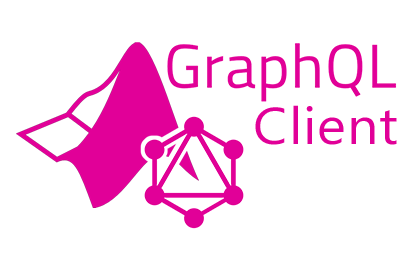

### How it works

Provided `GraphQL` class helps you to appropriately encode data, prepare query and call GraphQL endpoint via regular HTTP POST request under the hood according to official [documentation](https://graphql.org/learn/serving-over-http/).

### How to install

Download **GraphQL_Client.mltbx** from [releases](https://github.com/roslovets/MATLAB-GraphQL/releases) page and open it to install toolbox.

### How to embed in your project

If you want to make GraphQL Client a part of your project without installing toolbox just add `GraphQL.m` class to your project.

### Examples

#### Example 1. Simple query

Basic GraphQL request with datetime decoding

% Define endpoint URL
url = 'https://api.graphql.jobs/';
% Compose query
query = 'query{jobs{title,locationNames,postedAt}}';
% Create GraphQL object with predefined web options
g = GraphQL(url, 'Query', query);
% Execute query
res = g.execute();
% Extract data
jobs = struct2table(res.data.jobs);
% Convert dates to datetime format
jobs.postedAt = GraphQL.datetime(jobs.postedAt);
head(jobs, 3)

ans = 3×3 table
                        title                              locationNames                  postedAt        
    _____________________________________________    __________________________    _______________________

    {'Senior Fullstack Engineer - Platform'     }    {'San Francisco'         }    2019-08-12T20:19:52.00Z
    {'Full Stack JavaScript Developer'          }    {'Remote / Berlin'       }    2019-08-12T12:58:28.00Z
    {'Senior Software Engineer, API Development'}    {'London, United Kingdom'}    2019-08-12T10:47:47.00Z


#### Example 2. Encoding data

How to encode MATLAB structure to query string

% Define endpoint URL
url = 'https://countries-274616.ew.r.appspot.com/';
% Create filter structure
filter = struct('filter', struct('area_gt', 1e7));
% Encode filter structure to string
filterstr = GraphQL.encode(filter);
% Compose query with filter argument
query = sprintf('query{Country(%s){name,area,population}}', filterstr);
% Create GraphQL object
g = GraphQL(url, 'Query', query);
% Execute query
res = g.execute();
% Extract data
res.data.Country

ans = 2×1 struct array with fields:
    name
    area
    population


#### Example 3. Add API key (change request options)

How to modify HTTP request options

% Define endpoint URL
url = 'https://api.graphql.jobs/';
% Define your API key
apiKey = 'your_api_key';
% Create weboptions object (builtin in MATLAB) with specified header fields
opts = weboptions('HeaderFields', {'apiKey' apiKey});
% Optionally increase request timeout (usefull for heavy requests)
opts.Timeout = 10;
% Compose query
query = 'query{jobs{title,locationNames,postedAt}}';
% Create GraphQL object with predefined web options
g = GraphQL(url, 'Query', query, 'WebOptions', opts);
% Execute query
res = g.execute();

2020, [Pavel Roslovets](https://roslovets.github.io)